%compare beam squint compensation between different methods
clc;
clear all;
%close all;
%use different values of tmax
%TMax = (1e-12)*(200:10:400); 


%% system parameters
Sysparam = struct();

Sysparam.Nt = 256;
Sysparam.Nr = 4;
Sysparam.Ns = 4;
Sysparam.fc = 3*1e11;%carrier frequency 
B = [5,10,15,30]*1e9;
%B = Sysparam.fc.*(0:0.001:0.1);/
Sysparam.K = 129;  %number of sub-carriers
Sysparam.M = 16; %number of TTDs for each RF chain
Sysparam.N = Sysparam.Nt/Sysparam.M; %number of PSs for each TTD
Sysparam.L = 1 ; % number of paths equals to number of RF chains
%% simulation parameters
Simparam = struct();
Simparam.psi = pi*rand(Sysparam.L,1)-0.5*pi; %AoA;
Simparam.P = -20:5:15;% transmit power in dB
Simparam.Rho = 10.^(Simparam.P/10); %transmit power
Simparam.Niter = 50; %channel realizations

%Simparam.phi = pi*rand(Sysparam.L,1)-0.5*pi %AoD;
Simparam.phi = 0.45*pi*ones(Sysparam.L,1);%AoD;
%Simparam.phi = pi*((0.5-1/3)*rand(Sysparam.L,1)+1/3) %AoD;
SpatialDirection = sin(Simparam.phi);

set(0, 'defaultlinelinewidth', 1); set(0, 'defaultlinemarkersize', 2);
set(0, 'defaultaxesfontsize', 20); set(0, 'defaulttextfontsize', 20); 

for niter = 1:length(B)
Sysparam.f = B(niter); %bandwidth 
for k =1:Sysparam.K 
    Sysparam.F(k,1) = Sysparam.fc +(Sysparam.f/Sysparam.K)*(k-1-(Sysparam.K-1)/2); % sub-carrier frequency
end 
% relative frequencies
Sysparam.xi = Sysparam.F/Sysparam.fc; 
for l = 1:Sysparam.L
    a(:,l) = arrayResponse(sin(Simparam.phi(l)),Sysparam.Nt);
    for k = 1:Sysparam.K
         b(:,k,l) = arrayResponse(Sysparam.xi(k)*sin(Simparam.phi(l)),Sysparam.Nt);
         arrayGain(k,l,niter) = abs(a(:,l)'*b(:,k,l));
    end
end
fig = plot(1:Sysparam.K,arrayGain(:,:,niter),'DisplayName',strcat('B = ',num2str(B(niter)/1e9),' GHz'))
set(fig,'LineWidth',4)
grid on
hold on 
xlim([1,Sysparam.K]) 
end 

fig =   Line (B =5 GHz) with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 2
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 … ]
              YData: [0.0433 0.0282 0.0125 0.0036 0.0204 0.0376 0.0553 0.0735 0.0921 0.1112 0.1307 0.1506 0.1708 0.1914 0.2123 0.2334 0.2548 0.2765 0.2983 0.3203 0.3424 0.3647 0.3870 0.4094 0.4317 0.4541 0.4764 0.4986 0.5208 0.5427 0.5645 0.5861 … ]

  Show 

fig =   Line (B =10 GHz) with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 2
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 … ]
              YData: [0.0428 0.0281 0.0125 0.0036 0.0203 0.0373 0.0546 0.0718 0.0889 0.1056 0.1218 0.1374 0.1520 0.1657 0.1780 0.1890 0.1984 0.2060 0.2118 0.2156 0.2172 0.2165 0.2135 0.2080 0.2001 0.1895 0.1763 0.1606 0.1422 0.1212 0.0977 0.0717 … ]

  Show 

fig =   Line (B =15 GHz) with properties:

              Color: [0.9290 0.6940 0.1250]
          LineStyle: '-'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 2
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 … ]
              YData: [0.0421 0.0279 0.0125 0.0036 0.0203 0.0369 0.0533 0.0690 0.0835 0.0966 0.1079 0.1169 0.1235 0.1274 0.1283 0.1262 0.1210 0.1126 0.1011 0.0867 0.0695 0.0499 0.0281 0.0045 0.0203 0.0459 0.0718 0.0973 0.1218 0.1448 0.1657 0.1837 … ]

  Show 

fig =   Line (B =30 GHz) with properties:

              Color: [0.4940 0.1840 0.5560]
          LineStyle: '-'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 2
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 79 … ]
              YData: [0.0383 0.0269 0.0124 0.0036 0.0199 0.0348 0.0469 0.0549 0.0580 0.0556 0.0478 0.0351 0.0186 3.6789e-04 0.0201 0.0386 0.0542 0.0653 0.0706 0.0694 0.0614 0.0471 0.0276 0.0045 0.0202 0.0442 0.0652 0.0810 0.0899 0.0906 0.0826 0.0661 … ]

  Show 

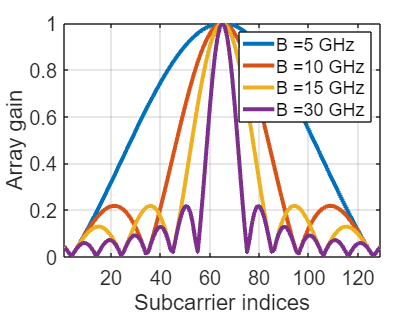

xlabel('Subcarrier indices')
ylabel('Array gain')
legend show
hold off

% AverageGain = squeeze(sum(arrayGain,1))/Sysparam.K;
% plot(0:0.001:0.1,AverageGain)
% ylabel('Average Array Gain')
% grid on 
% xline(0.1)
% xlabel('B/f_c')
%title('K = 129')
%find(arrayGain(:,:,4)<0.2)

%plot(0:0.001:1,squeeze(arrayGain(1,1,:)))
%plot(0:0.001:1,squeeze(arrayGain(2,1,:)))
%plot(0:0.001:1,squeeze(arrayGain(3,1,:)))